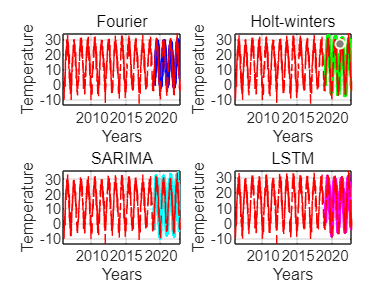

figure
clc
clear all
load("matlab4.mat")
load("matlab5.mat")
load("YPredForLSTM.mat")
load("YPredForHW.mat")
load("YPredForSAR.mat")
% load("YPredForS.mat")
hold off
times1 = 2006:(1/365):(2018+364/365);
times2 = 2019:(1/365):(2022+(364-80)/365);
times3 = 2006:(1/365):(2022+(364-80)/365);

% visualisation of results
subplot(2,2,1)
for i = 4746:6125
    YPredForF(i-4745) = Fourier_8(i);
end
plot(times2,YPredForF,'b','LineWidth',2)
hold on
plot(times3,PekingTemp,'--r')
xlabel("Years") ,ylabel("Temperature")
title("Fourier")
grid on
hold off

subplot(2,2,2)
plot(times2,YPredForHW,'g','LineWidth',2)
hold on
plot(times3,PekingTemp,'--r')
xlabel("Years") ,ylabel("Temperature")
title("Holt-winters")
grid on
hold off

subplot(2,2,3)
plot(times2,YPredForSAR,'cyan','LineWidth',2)
hold on
plot(times3,PekingTemp,'--r')
xlabel("Years") ,ylabel("Temperature")
title("SARIMA")
grid on
hold off


subplot(2,2,4)
plot(times2,YPredForLSTM,'m','LineWidth',2)
hold on
plot(times3,PekingTemp,'--r')
xlabel("Years") ,ylabel("Temperature")
title("LSTM")
grid on
hold off